more %function hw6_primer
% Today we'll be working on "Synthetic Biology". This is a movement to
% bring engineering principles to designing biological systems. In this
% tutorial we'll be designing and characterizing an AND gate.

## Pathway Diagram

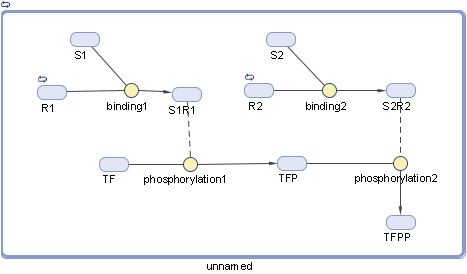

**Binding Reaction:**


$${\Delta}AB = kforward[A][B] - kreverse[AB]$$


**Enzyme Kinetics:**


$${\Delta}P = {Vmax[E][S] \over {km + [S]}}$$


## Reaction Rates:[TF]:[S];[TFP]:[S]

- 
$$R_{binding1}: k_{forward}[S1][R1] - k_{reverse}[S1R1]$$


- 
$$R_{binding2}: k_{forward}[S2][R2] - k_{reverse}[S2R2]$$


- 
$$R_{phosphorylation1}: {Vmax[S1R1][TF] \over {km + [TF]}}$$


- 
$$R_{phosphorylation2}: {Vmax[S2R2][TFP] \over {km + [TFP]}}$$


## Default Parameters and Concentrations (arbitrary units)

We will use the following default values. We may vary some of these values to investigate their effect on the concentration of P.

- $[S1] = 8$, $[S2] = 9$

- 
$$[R1] = [R2] = [TF] = 10$$


- All other species have initial concentration zero.

## **Defining the pathway**

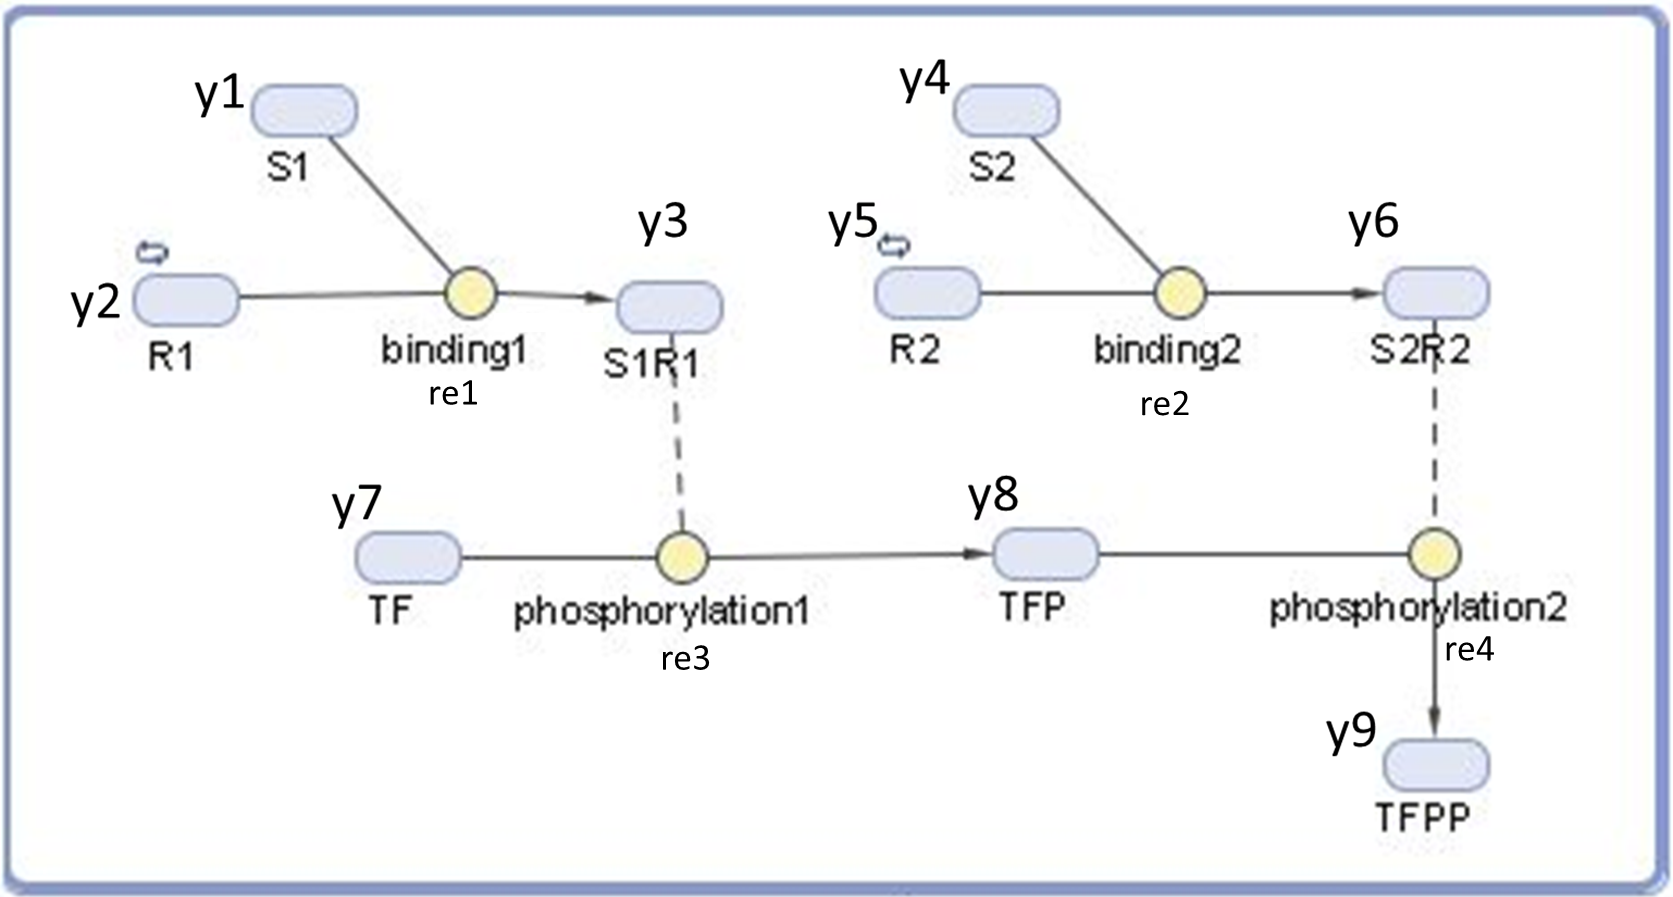

re1 (d(S1R1)/dt) = kf*y(1)*y(2) - kr*y(3);  (y(1):S1; y(2):R1; y(3):S1R1)

re2 (d(S2R2)/dt)= kf*y(4)*y(5) - kr*y(6);  (y(4):S2; y(5):R2; y(6):S2R2)

re3 (d(TFP)/dt)= Vmax*y(7)*y(3)/(km + y(7)) ;          (y(7):TF)

re4 (d(TFPP)/dt)= Vmax*y(8)*y(6)/(km + y(8)) ;        (y(8):TFP; y(9):TFPP)

**Establish the ODE**

dy = zeros(9,1);

dy(2) = -re1;

dy(3) = +re1;

dy(5) = -re2;

dy(6) = +re2;

dy(7) = -re3;

dy(8) = +re3-re4;

dy(9) = +re4;

## **andpathwaysimple.m kf=8, vmax=2, kr = 4, km = 2;**

## **Y0([2, 5, 7]) = 10  (R1, R2,TF) (arbitrary)**

## **ode23 (**https://www.mathworks.com/help/matlab/ref/ode23.html)

`[`[`t`](https://www.mathworks.com/help/matlab/ref/ode23.html#bu5ypsv_sep_shared-t)`,`[`y`](https://www.mathworks.com/help/matlab/ref/ode23.html#bu5ypsv_sep_shared-y)`] = ode23(`[`odefun`](https://www.mathworks.com/help/matlab/ref/ode23.html#bu5ypsv_sep_shared-odefun)`,`[`tspan`](https://www.mathworks.com/help/matlab/ref/ode23.html#bu5ypsv_sep_shared-tspan)`,`[`y0`](https://www.mathworks.com/help/matlab/ref/ode23.html#bu5ypsv_sep_shared-y0)`)`, where `tspan = [t0 tf]`, integrates the system of differential equations *y*'=*f*(*t*,*y*) from `t0` to `tf` with initial conditions `y0`. Each row in the solution array `y `corresponds to a value returned in column vector `t`.

## **Running** the pathway

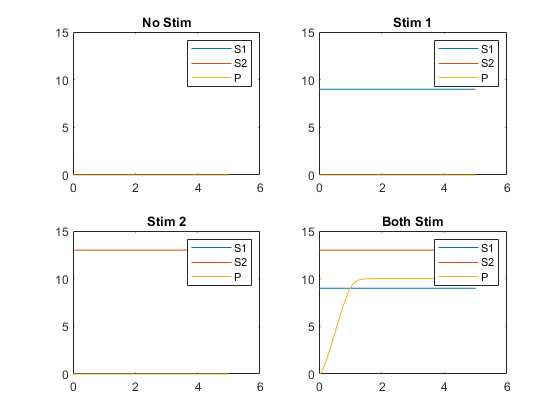

% First we need some initial conditions
Y0 = zeros(9,1);
Y0([2, 5, 7]) = 10; % y(2):R1;y(5):R2;y(7):TF

% Then we need to simulate each of the four conditions.

% no stimulation y(1):S1=0 y(4):S2=0
Y0([1, 4]) = [0, 0]; 
[T, Y] = ode23s(@andpathwaysimple, [0, 5], Y0);

% stimulation of receptor 1 only, S1(y1) =9, S2(y4)=0
Y0([1, 4]) = [9, 0];
[Ta, Ya] = ode23s(@andpathwaysimple, [0, 5], Y0);

% stimulation of receptor 2 only,  S1(y1) =0, S2(y4)=13
Y0([1, 4]) = [0, 13];
[Tb, Yb] = ode23s(@andpathwaysimple, [0, 5], Y0);

% stimulation of both receptors S1 and S2  S1(y1) =9, S2(y4)=13
Y0([1, 4]) = [9, 13];
[Tab, Yab] = ode23s(@andpathwaysimple, [0, 5], Y0);

% And now we need to plot the values.
bmes_fig fourcases
subplot(2,2, 1), plot(T, Y(:, [1,4,9])); legend({'S1' 'S2' 'P'})
ylim([0, 15]), title('No Stim')

subplot(2,2,2), plot(Ta, Ya(:, [1,4,9])); legend({'S1' 'S2' 'P'})
ylim([0, 15]), title('Stim 1')

subplot(2,2,3), plot(Tb, Yb(:, [1,4,9])); legend({'S1' 'S2' 'P'})
ylim([0, 15]), title('Stim 2')

subplot(2,2,4), plot(Tab, Yab(:, [1,4,9])); legend({'S1' 'S2' 'P'})
ylim([0, 15]), title('Both Stim')

**Figure Caption:** The designed pathway follows the correct stimulation pattern. Upper left: No stimulation results in no signal. Upper-right & Lower-left: Stimulating with a single input produces no response. Lower Right: Stimulation with both inputs results in an output.

## Characterize important features

So, this works, but we're engineers. We need to make sure it has particular characteristics. We'll put some hard numbers on these requirements so we can be quantitative.

**- A response is defined as anything of P over 8 units (Y(:9)). - The response must occur within 1 second with S1=S2=1.0 unit. - The system should be able to "detect" a stimulus of at least 8 units in less than one second.  **

Y0([1, 4]) = [1, 1], S1 and S2

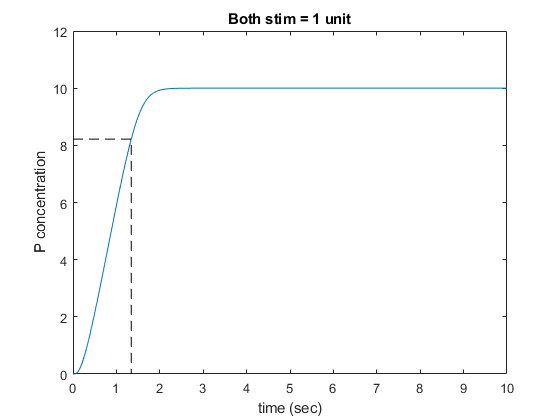

Response above 8 units detected at 1.341714 seconds.


bmes_fig responsetimes1
clf
% Get the response time of a single simulation.
Y0([1, 4]) = [1, 1];
[T, Y] = ode23s(@andpathwaysimple, [0, 10], Y0);
plot(T,Y(:,9)); title('Both stim = 1 unit'); 
xlabel('time (sec)'); ylabel('P concentration');

pos = find(Y(:,9)>=8.0, 1, 'first');  % find the first datapoint? 8.0. 
if isempty(pos)
	fprintf('No response detected above 8 units.\n');
else
	rtime = T(pos); % find the response time
	fprintf('Response above 8 units detected at %f seconds.\n',rtime);
	hold on;
	plot([0 rtime rtime], [Y(pos,9) Y(pos,9) 0], 'k--')
	hold off;
end

system not fast enough to satifssfy requirement

**Check detection time threshold (studyresponsetime function)**

**Under the following initial conditions, the system does not meet our requirements. **

- initial conditions in andpathwaysimple.m kf=8, vmax=2, kr = 4, km = 2;

- Y0([2, 5, 7]) = 10 (R1=2, R2=5,TF=7)

- S1(y1)=1 and S2(y4)=1 

Now, we are simulating different inputs of S1 and S2 from 0.1 to 5 (checks = linspace(0.1, 5, 20))

Y0([1, 4]) = checks(i);

[T, Y] = ode23s(dyfunction, [0, 10], Y0);

find the response time for >8.0 units

plot  Y0 vs response time

**Under what Y0([1, 4]), does the system meet the response time requirement**

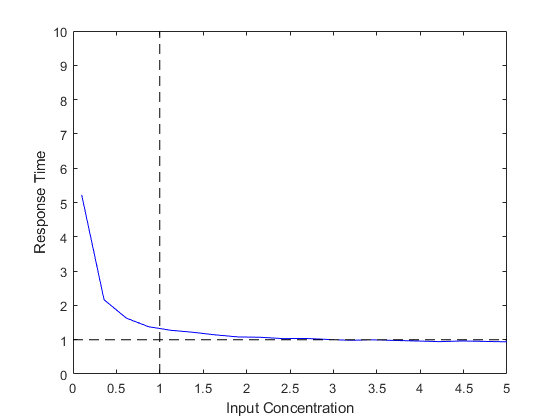

bmes_fig responsetimes2
studyresponsetime(@andpathwaysimple);

**Figure Caption:** The original design does not have the required response time towards the bottom of the detection threshold. The blue line shows the response time (time for the signal to exceed 8 units) as a function of the input concentrations. The system needs to be re-implemented to meet the design requirements.

**What about increasing the reaction rates?  **

Let's increase kf from 8 to 12 and vmax from 2 to 4

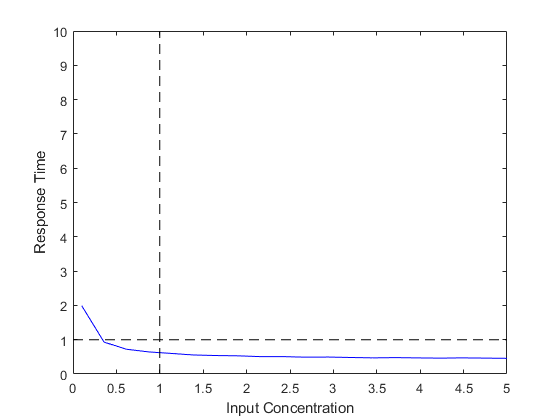

% We could create a copy of andpathway with faster reaction constants, hard code your faster kf and vmax. increase kf from 8 to 12 and vmax from 2 to 4
%studyresponsetime(@andpathwaysimple_fastrxn);

% But writing a whole new file is kind of redundant and error-prone.
% We rewrote a new version, andpathway() to allow reaction constants to be
% specified as inputs, so let's utilize that.
% We could write a separate file that just calls this more general andpathway()
% function and returns its output. But we can use anonymous function to avoid
% writing a separate file.
bmes_fig responsetimes3
modifiedpathway = @(t,y)andpathway(t,y, 'kf',12, 'vmax',4);  % increase kf from 8 to 12 and vmax from 2 to 4
studyresponsetime(modifiedpathway);

**Figure Caption:** Inreasing the forward constant of the reaction coeficients by 20% allowed us to reach our design goals. The blue line shows the response time (time for the signal to exceed 8 units) as a function of the input concentrations for the original system while the green line indicates the re-designed system.

Or you can hard-code the new Kf and Vmax in the andpathwaysimple2 function. It generates the same results. 

bmes_fig responsetimes3
studyresponsetime(@andpathwaysimple2);

Unrecognized function or variable 'andpathwaysimple2'.
Error in odearguments (line 90)
f0 = feval(ode,t0,y0,args{:});   % ODE15I sets args{1} to yp0.
Error in ode23s (line 121)
    = odearguments(FcnHandlesUsed, solver_name, ode, tspan, y0, options, varargin);
Error in 

## Parameter Scan

We tried some larger values for reaction constants and got lucky with our design that it can detect the signal within 1 second. Let's do this more systematically and analyze the response time for varying values of the reaction constants. We'll only look at the kf and vmax constants.

## Individual Parameter Scan  scan for kf with vmax =2,  keeping Y0([1, 4]) = 1.

Can the system achieve the required response time with vmax=2?

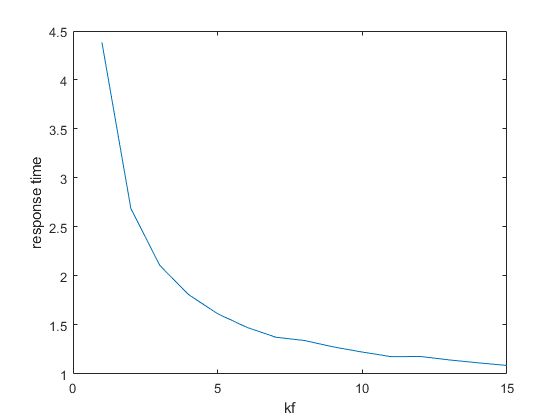

figure;
kfs = 1:15;
kf_response = zeros(1,numel(kfs));
Y0([1, 4]) = 1;
hwaitbar = waitbar(0,'Please wait');
for i=1:numel(kfs) % for any given kf, find the response time. 
	waitbar(i/numel(kfs), hwaitbar);
	modifiedpathway = @(t,y)andpathway(t,y, 'kf',kfs(i));
	[T, Y] = ode23s(modifiedpathway, [0, 10], Y0);
	pos = find(Y(:,9)>=8.0, 1, 'first');
	if isempty(pos);  kf_response(i) = nan;
	else  kf_response(i) = T(pos); end
end
delete(hwaitbar);

plot(kfs, kf_response);
xlabel('kf'), ylabel('response time');

## Scanning pairs of parameters

kfs = 1:0.2:15;
vmaxs = 1:0.5:10;
kfvmax_response=zeros(numel(kfs), numel(vmaxs));
Y0([1, 4]) = 1;
for i = 1:numel(kfs) %  loop through kf
	bmes_progress('kf', [i-1 numel(kfs)]);
	for j = 1:numel(vmaxs) % loop through vmax
		bmes_progress('vmax', [j-1 numel(vmaxs)]);
		modifiedpathway = @(t,y)andpathway(t,y, 'kf',kfs(i), 'vmax',vmaxs(j));
    [T, Y] = ode23s(modifiedpathway, [0, 10], Y0);
    pos = find(Y(:,9)>=8.0, 1, 'first');
    if isempty(pos);  kfvmax_response(i,j) = nan;
		else  kfvmax_response(i,j) = T(pos); end
	end
	bmes_progress('vmax',1);
end
bmes_progress('kf',1);

bmes_fig surf
x = repmat(kfs', 1, numel(vmaxs));
y = repmat(vmaxs, numel(kfs), 1);
surf(x,y,kfvmax_response), xlabel('kf'), ylabel('vmax'),zlabel('responsetime')

**Heatmap with imagesc**

when vmax=2, none of kf will satisfy the response time requirement. When kf>8 and vmax>6, most the combinations will generate satisfactory response times. 

bmes_fig image; clf
%NOTE: for images, rows are shown as y-axis and columns correspond to x-axis.
imagesc(y(:),x(:),kfvmax_response), colorbar;
xlabel('vmax'), ylabel('kf');
hold on;
contour(x,y,kfvmax_response,[1,1],'Color',[1 1 1]);
hold off;

## Appendix: Supplementary Files

type andpathway.m

type studyresponsetime